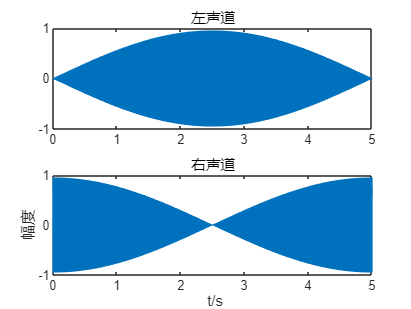

clc;clear;
A=1;
f=800;
Fs=10*f;
N=5*Fs;
t=(0:N-1)/Fs ;%时域范围
x=A*sin(2*pi*f*t);
s1=x.*sin(0.1*2*pi*t);%左声道
s2=x.*cos (0.1*2*pi*t);%右声道
sound([s1',s2'],Fs);
figure;
subplot(2,1,1);
plot(t,s1);
title('左声道');
subplot(2,1,2);
plot(t,s2);
title('右声道');
xlabel(' t/s') ;
ylabel('幅度');